clear; close all; clc;

**Question 4: Write a Haar wavelet denoiser**

Take any (monochrome) image of your choice. Calculate the Haar wavelet transform of this image. Plot some of the coeffecients and explain what you see.

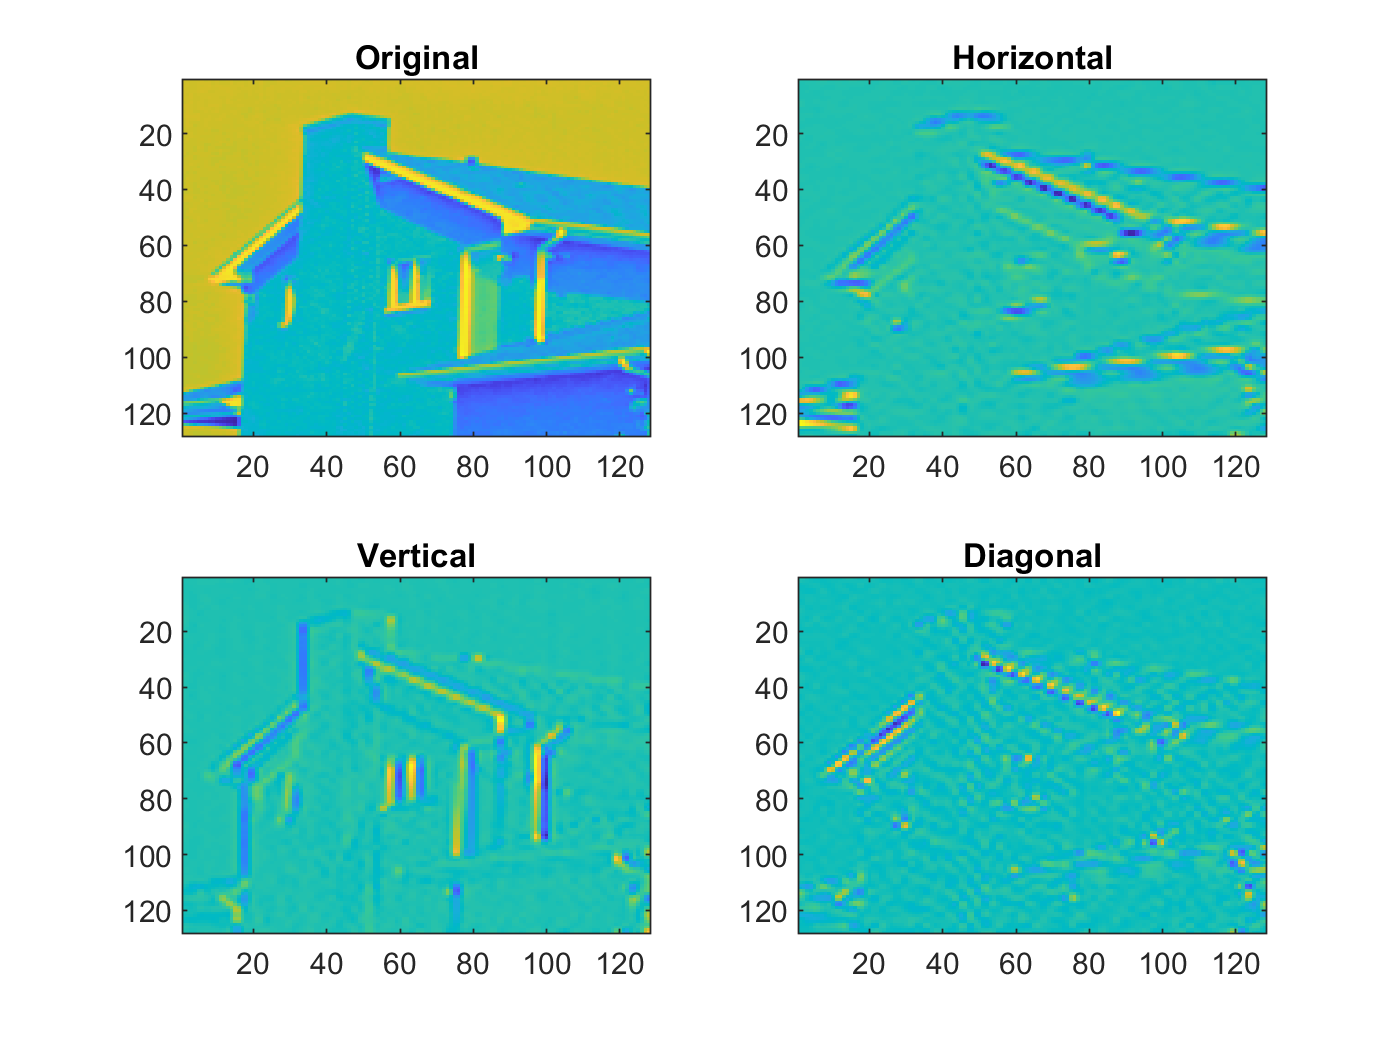

img = im2double(imread('house.png'));

[a, h, v, d] = haart2(img);

figure;
subplot(2, 2, 1); imagesc(img); title('Original')
subplot(2, 2, 2); imagesc(imresize(h{1}, 2)); title('Horizontal')
subplot(2, 2, 3); imagesc(imresize(v{1}, 2)); title('Vertical')
subplot(2, 2, 4); imagesc(imresize(d{1}, 2)); title('Diagonal')

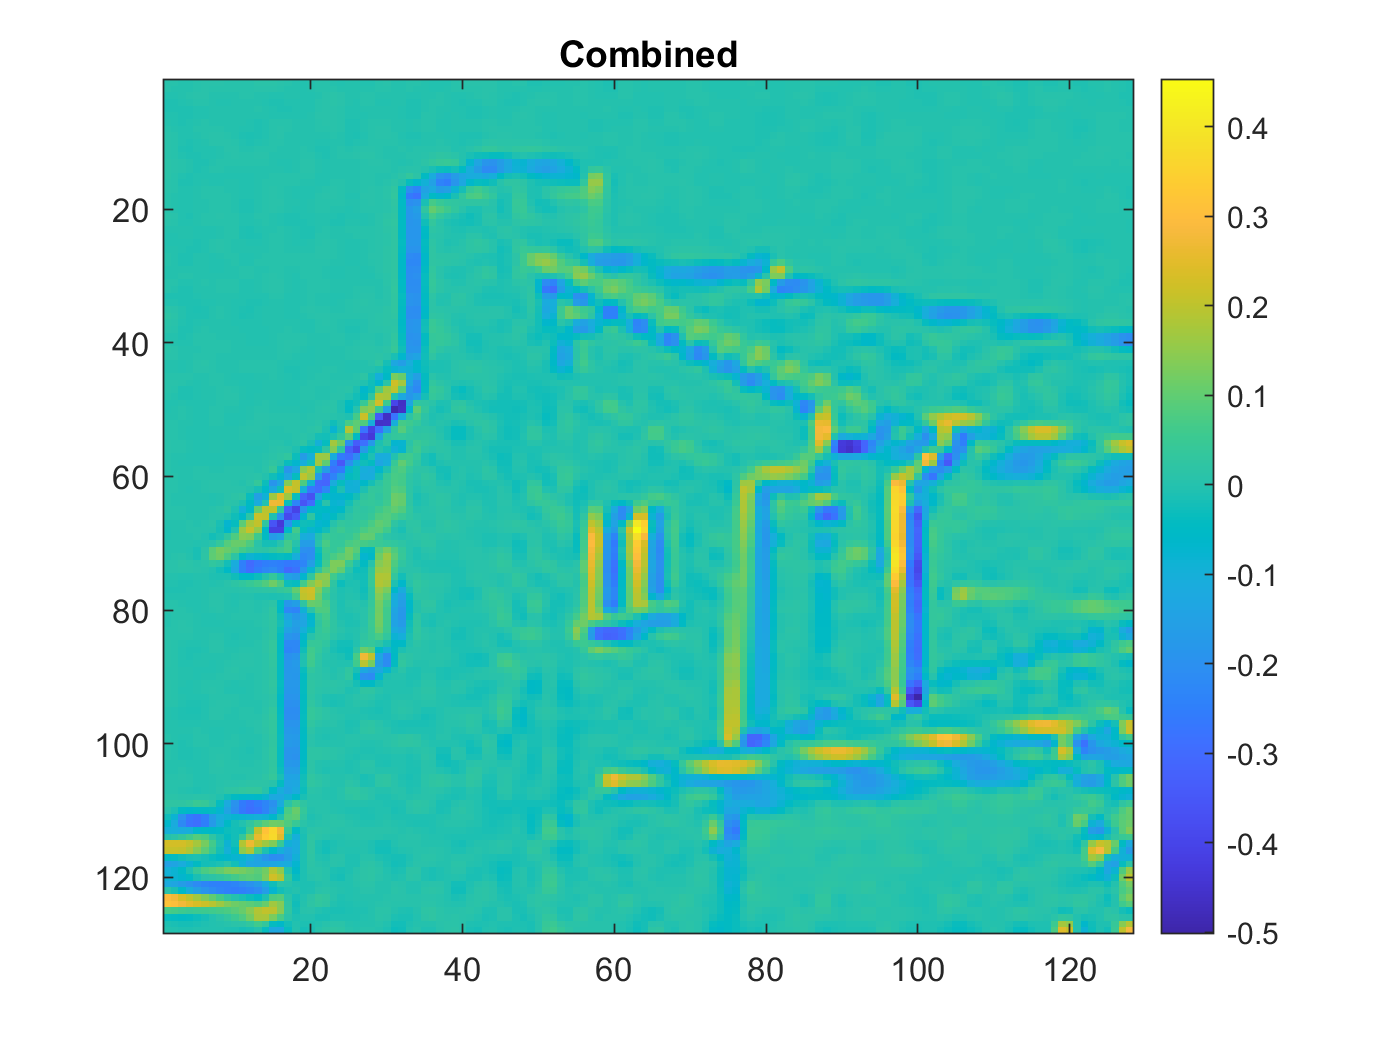

figure;
imagesc(imresize(h{1} + v{1} + d{1}, 2)); colorbar; title('Combined')

Reconstruct the image from the coefficients by calling the inverse wavelet transform. Check if your reconstructed image coincides with the original.

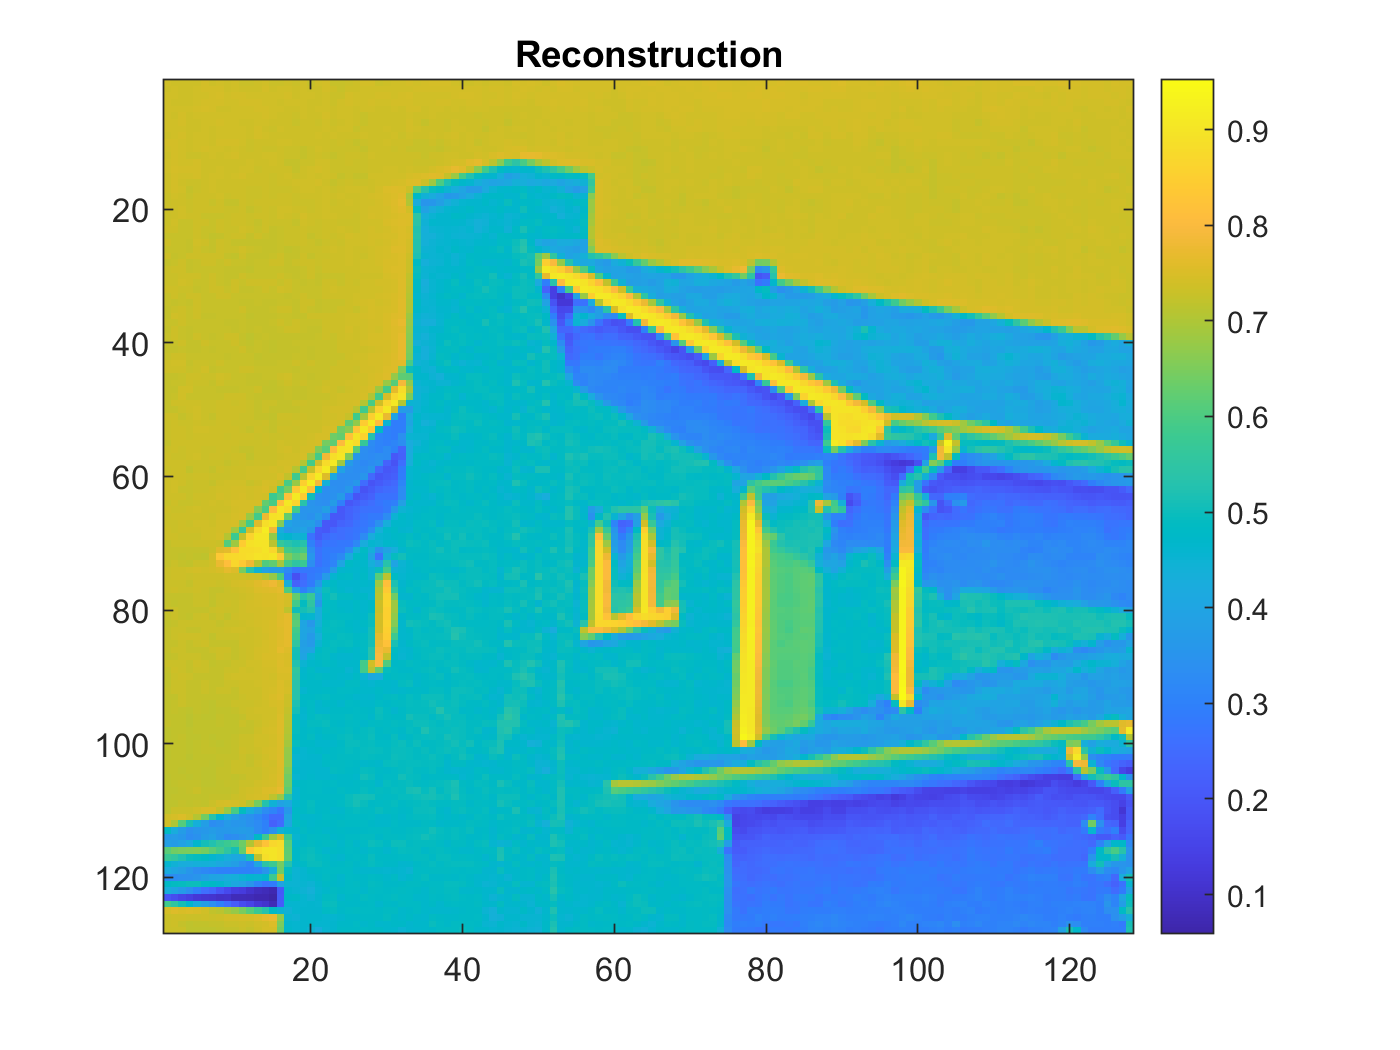

recon = ihaart2(a, h, v, d);

figure;
imagesc(recon);
colorbar;
title('Reconstruction')

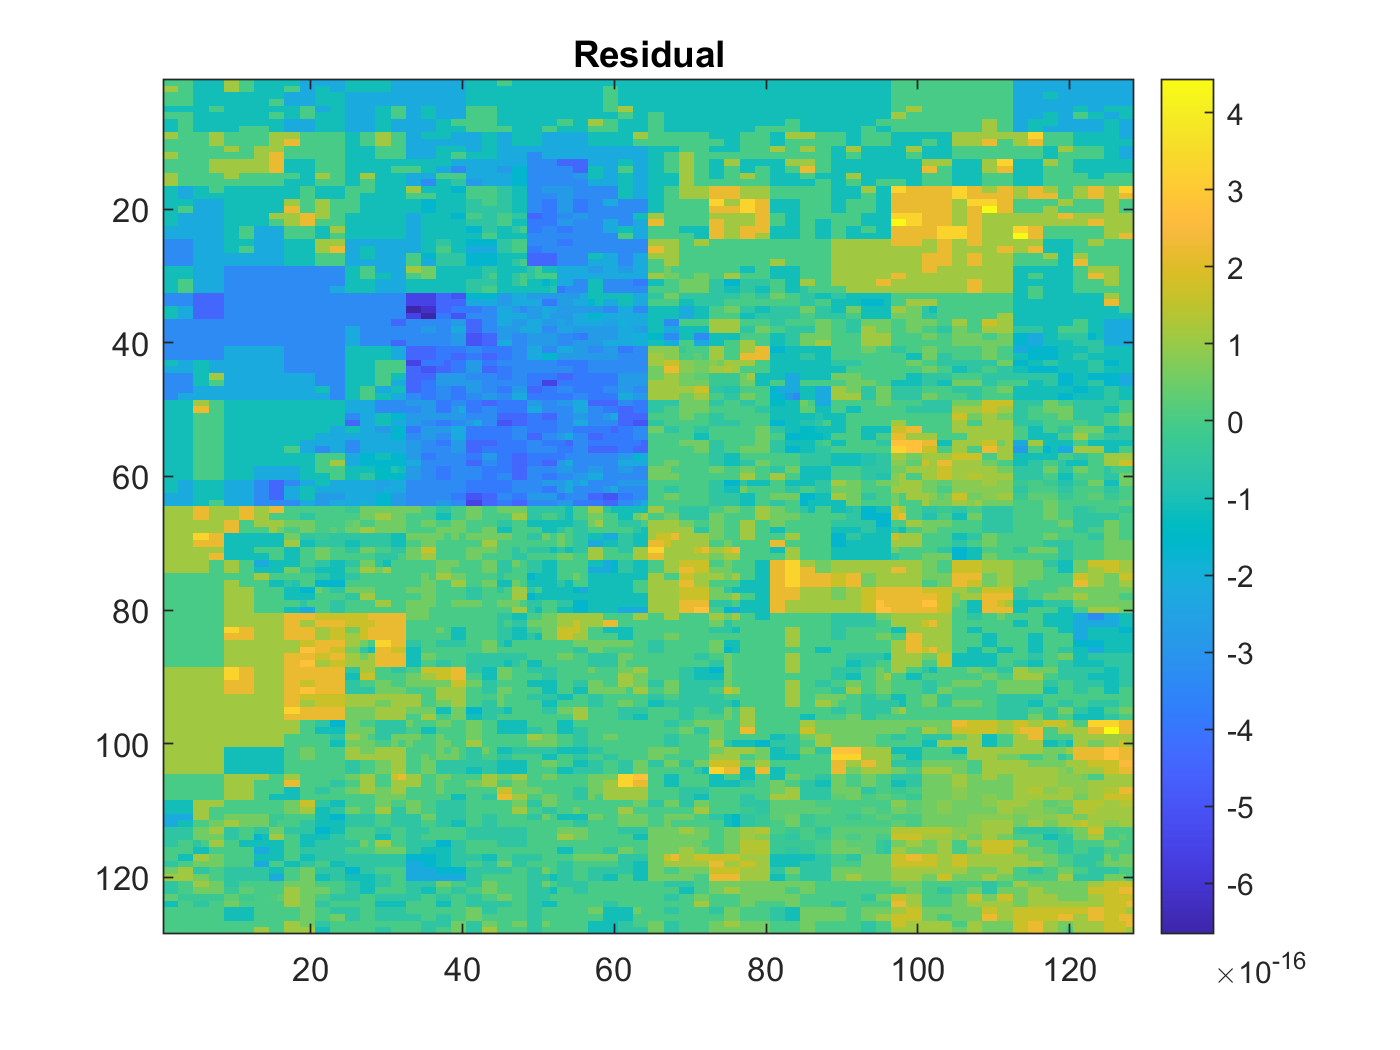

residual = recon - img;

figure;
imagesc(residual);
colorbar;
title('Residual')

Write a function that implements thresholding for a given range (the different scales of your wavelet coefficients) and threshold parameter, and form a modified image by performing the inverse wavelet transform on the thresholded coefficients.

img_noisy = img + rand(size(img)) * 0.2; % add noise
[a, h, v, d] = haart2(img_noisy);

range = 1 : 7;

%t_val = 0.06;
t_val = determine_threshold(h, v, d, range, 0.84)

index = 13761

t_val = 0.1022

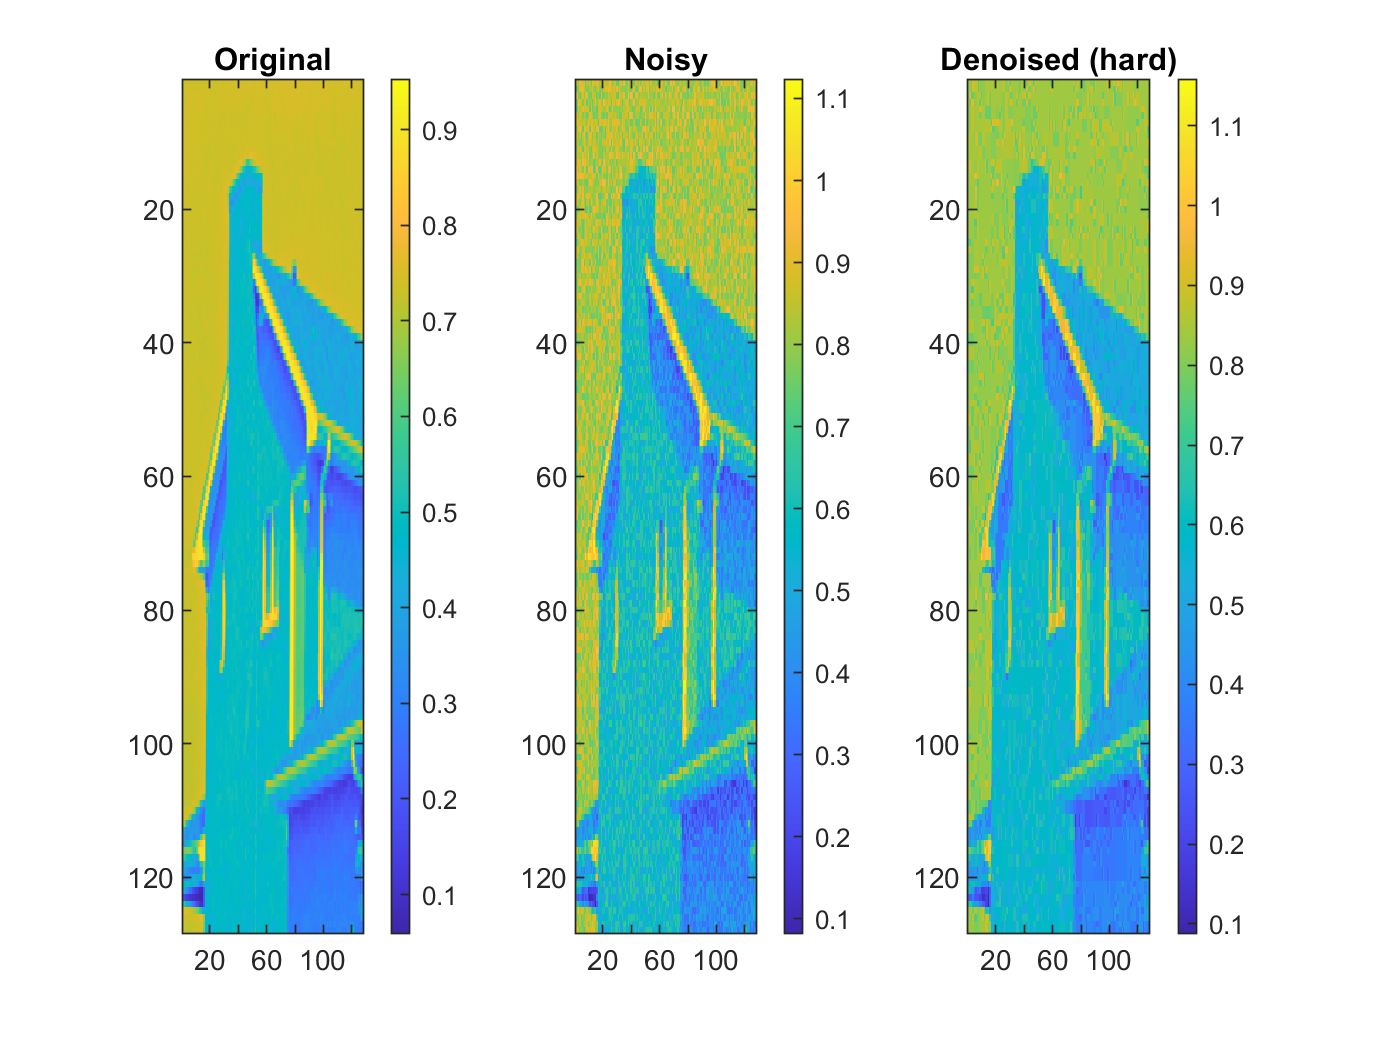

[hT, vT, dT] = thresholdFunction(h, v, d, range, t_val, 'h');

denoised = ihaart2(a, hT, vT, dT);

figure;
subplot(1, 3, 1); imagesc(img); colorbar; title('Original');
subplot(1, 3, 2); imagesc(img_noisy); colorbar; title('Noisy');
subplot(1, 3, 3); imagesc(denoised); colorbar; title('Denoised (hard)');

Create a noisy version of your original image and perform denoising by thresholding of the wavelet coefficients. Investigate the effect of changing the range and the threshold parameter.

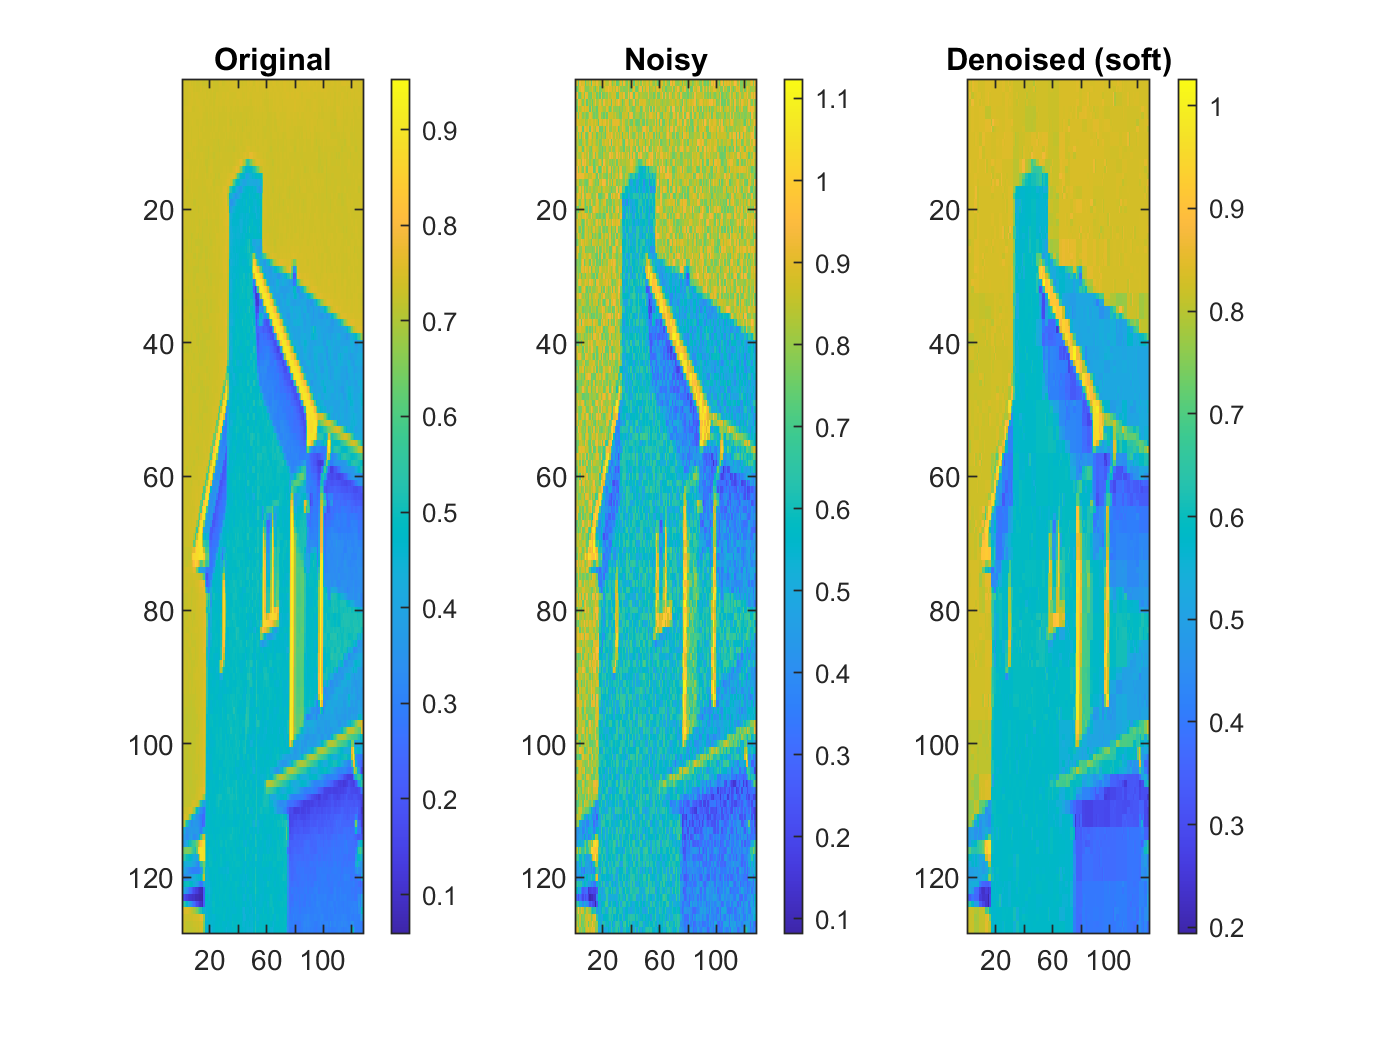

% Soft thresholding

[hT, vT, dT] = thresholdFunction(h, v, d, range, t_val, 's');
soft_denoised = ihaart2(a, hT, vT, dT);

figure;
subplot(1, 3, 1); imagesc(img); colorbar; title('Original');
subplot(1, 3, 2); imagesc(img_noisy); colorbar; title('Noisy');
subplot(1, 3, 3); imagesc(soft_denoised); colorbar; title('Denoised (soft)');

Limited level thresholding

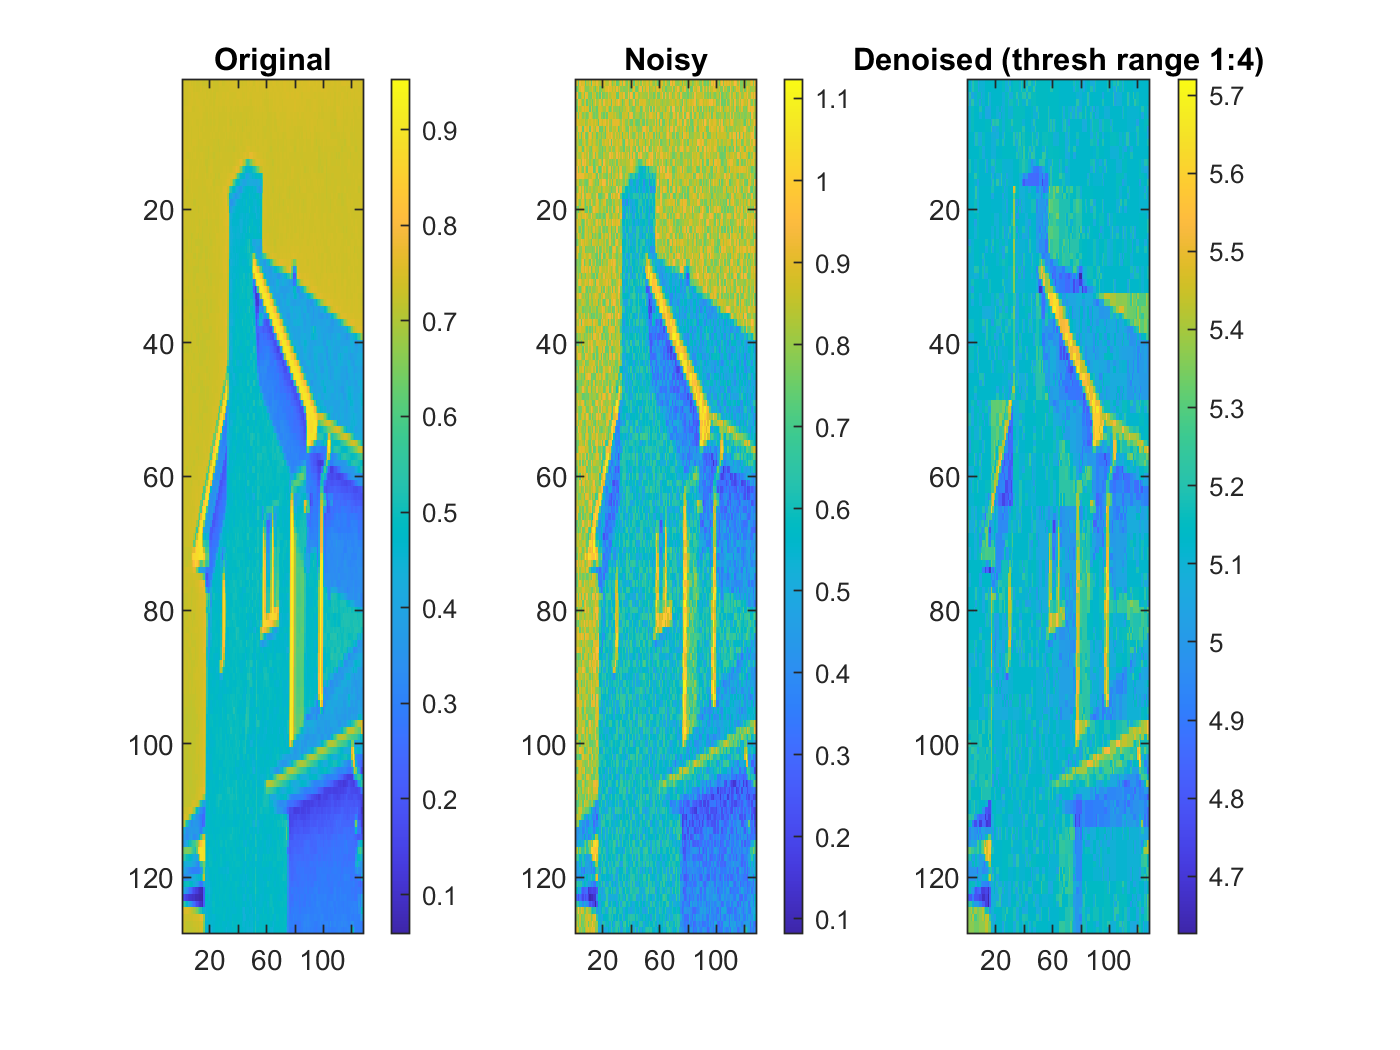

range = 1 : 4;

[hT, vT, dT] = thresholdFunction(h, v, d, range, t_val, 'h');

denoised_red_level = ihaart2(a, hT, vT, dT);

figure;
subplot(1, 3, 1); imagesc(img); colorbar; title('Original');
subplot(1, 3, 2); imagesc(img_noisy); colorbar; title('Noisy');
subplot(1, 3, 3); imagesc(denoised_red_level); colorbar; title('Denoised (thresh range 1:4)');